clear Var Sim Ctrl;clc;close all
 

## General Settings

### **Model Selection**

Sim.ModelName         = 'GCI_Ctrl_PLL_C2000';
Sim.SimOrHw         = "Sim";              % sim = 1, HW = 2
Sim.PlantOrMeas     = "HIL";              % Sim/Plant = 0, Sim/Measurments = 1, Sim/Actual Plant = 2, HW = 3, HIL = 4
Sim.ExternalOrComm = "External";
Sim.FltInj          = "Two Phase Flt";              % 0 == Two Phase Flt, 1 == Harmonics Injection, 2 == Three Phase Gnd, 3 == Freq Variation

### **Control Selection**

Sim.SOGISel         = "3P SOGI Disc";              % 1 == SRF PLL, 2 == DDSRF PLL, 3 == SOGI Const W, 4 == SOGI, 5 == DSOGI,6 == DDSRF SOGI,7 == SinglePhase SOGI, 8 == 3P SOGI Trap,9 == 1P SOGI Disc
Sim.CC_Enable      = 4;              % 0 == Vdq grid feed forward, 1 == Current Controller, 2 == CurrentControllerPosNegSeq
Sim.Modulation      = "SPWM";              % 1. SPWM / 2. SVPWM, 3. Adaptive
Sim.FiltDcOff       = "LPF";              % 0 == None, 1 == LPF, 2 == Movmean
Sim.ADC_UabcSensor      = "Three Currents";              % 0 == Meas AB only, 1 == Meas ABC
Sim.ADC_SE_or_Diff      = (0);              % 0 == Single Ended, 1 = diff ended
%%

### **Runtime Setting**

Sim.RunTime         = 1;
if Sim.SimOrHw == "Hw"
    Sim.ContSampleTime  = (1/10000);
else
    Sim.ContSampleTime  = 1*1e-6;
end


Sim.MeasLogTime          = ((100));
Sim.MeasFastSmplTime    = ((1000)*1e-6); % 1ms is possible
Sim.MeasSlowSmplTime    = ((5000)*1e-6); % 2ms is possible for all signals


## Plant Model Parametes (in C2000)

## 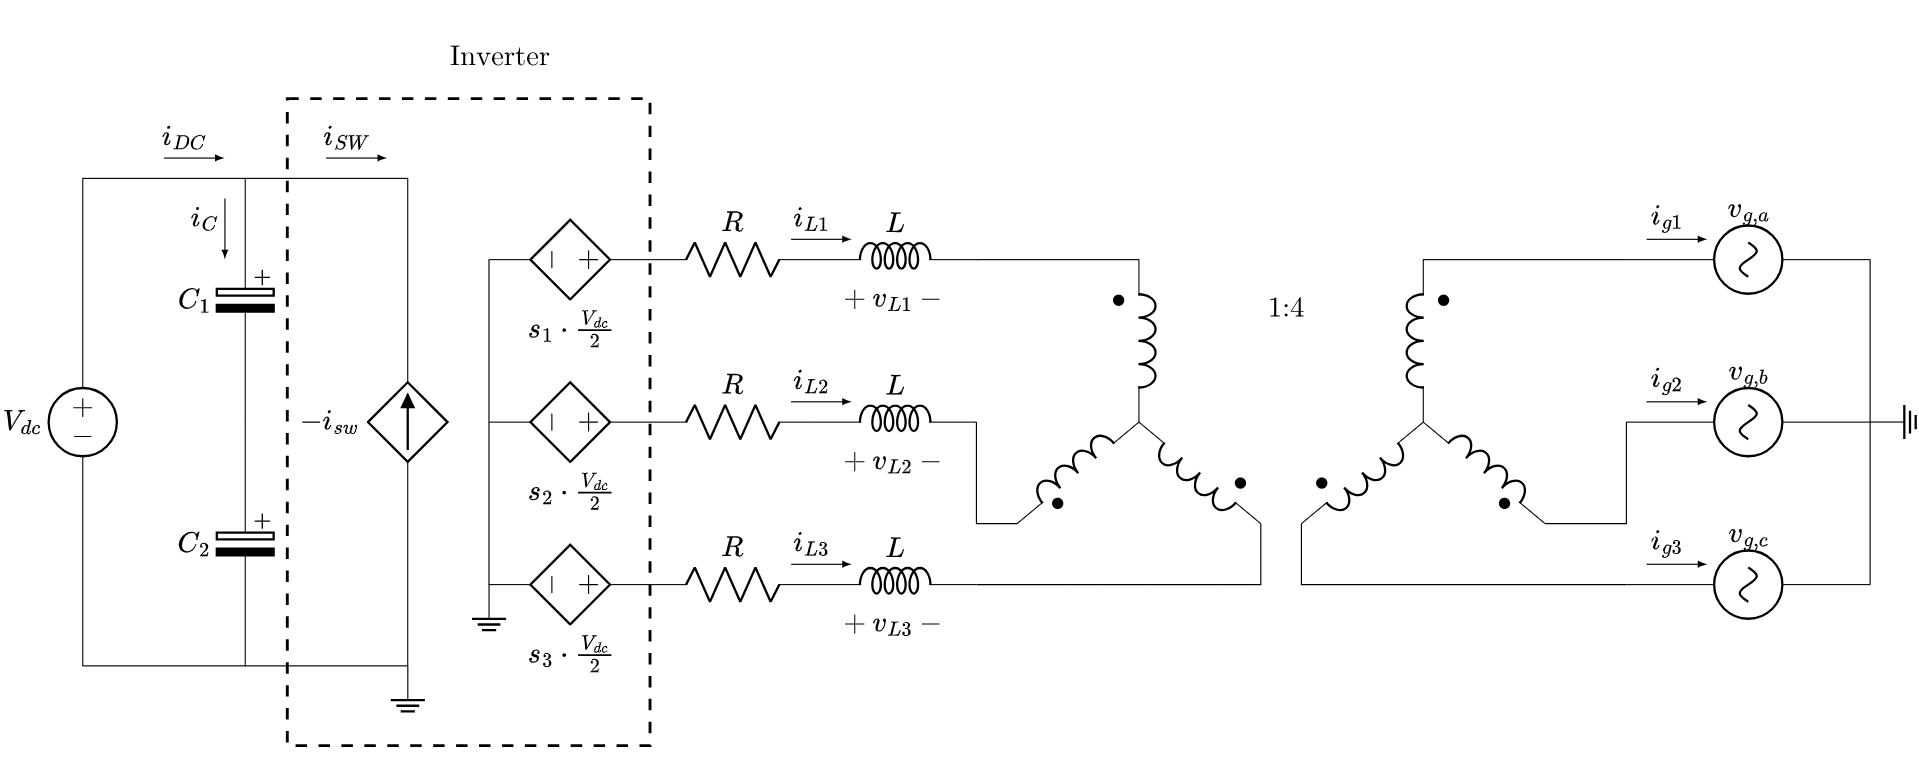

### **HVDC Settings**

Var.HVDC_V              = single(650); %% only for testing
Var.HVDC_C              = single(260*1e-6);
Var.HVDC_Cesr           = single(1e-4);
Var.HVDC_L              = single(10e-9);
Var.HVDC_Lesr           = single(1e-5);

### **Grid Settings**

% Grid Voltage
Var.Grid_Frq            = single(50);
% Connection Inductance
Var.Inductor_L          = single(2000*1e-6);
Var.Inductor_R          = single(1*1e-3);
% Connection Transformer
Var.Transformer_N          = single(4);
Var.Transformer_R1          = single(0.0992);
Var.Transformer_R2          = single(0.3);
Var.Transformer_L1          = single(0.6613e-3);
Var.Transformer_L2          = single(2e-3);

## Control Parameters (in C2000)

### **PWM**

Var.PWM_Freq            = single(10*1e3);
Var.PWM_Deadtime        = single(1*1e-6);

### **ADC**

ADC_Vref                = single(3);
Var.ADC_Res             = single(2^12);

### **PLL Controller**

Var.Pll_MaxDeltaFreq    = single(10*1e3);

### **Current Controller**

Var.CurCont_MaxVdVq     = single(400);

### **State Machine**

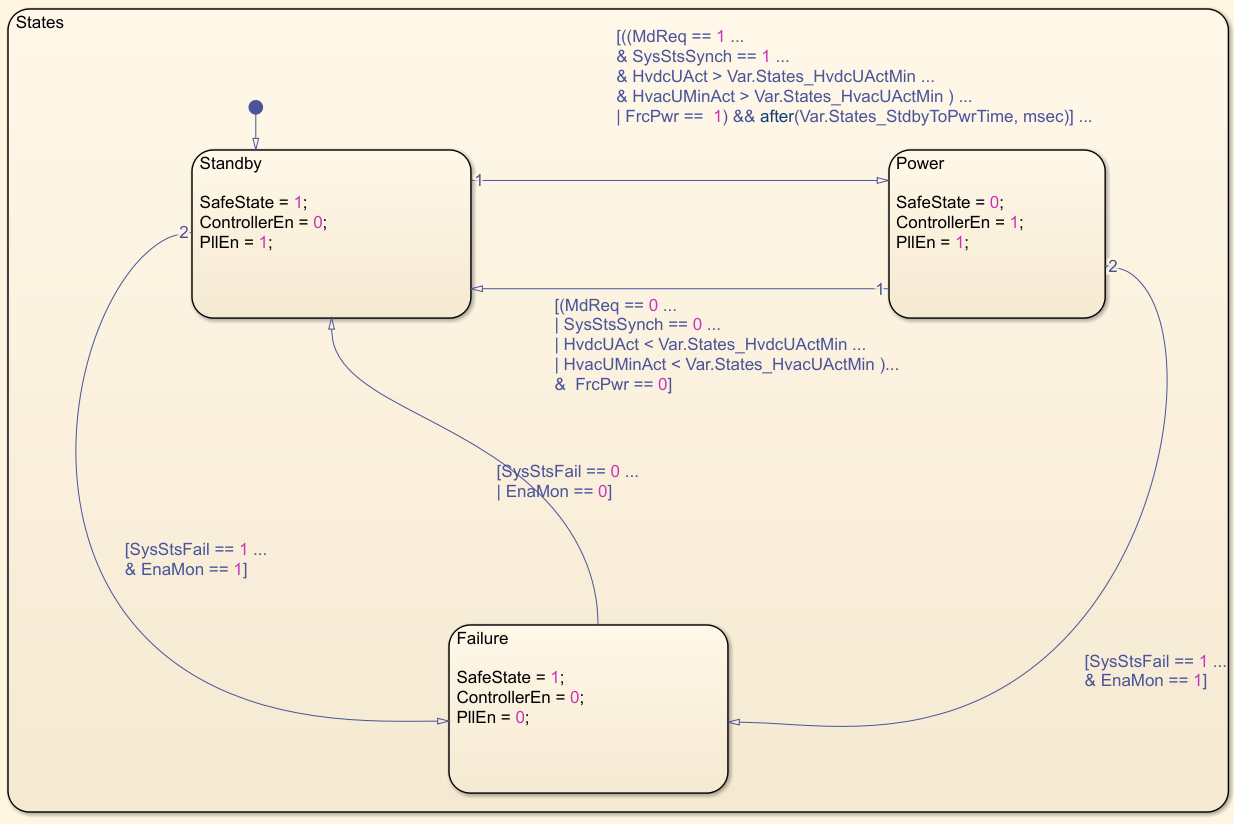

Var.States_HvdcUActMin = single(60);
Var.States_HvacUActMin = single(20);
Var.States_StdbyToPwrTime = single(0);

### **Diagnostics**

Var.Diag_IrmsOc = single(40);
Var.Diag_tIrmsDtc = single(1e-3);
Var.Diag_HvdcUOv = single(800);
Var.Diag_tHvdcUOvDtc = single(1e-3);
Var.Diag_AdcOorHLim = single(Var.ADC_Res-50);
Var.Diag_AdcOorLLim = single(50);
Var.Diag_tOorHDtc = single(1e-6);
Var.Diag_tOorLDtc = single(1e-6);

switch Sim.ADC_SE_or_Diff
    case 0
        Var.ADC_CH0_Gain        = single((ADC_Vref/(Var.ADC_Res-1))); % ADC REF/(MAX COUNT * VOLT/VALUE)
        Var.ADC_CH1_Gain        = single((ADC_Vref/(Var.ADC_Res-1))); 
        Var.ADC_CH2_Gain        = single((ADC_Vref/(Var.ADC_Res-1))); 
        Var.ADC_CH3_Gain        = single((ADC_Vref/(Var.ADC_Res-1))); 
        Var.ADC_CH4_Gain        = single((ADC_Vref/(Var.ADC_Res-1)));
        Var.ADC_CH5_Gain        = single((ADC_Vref/(Var.ADC_Res-1))); 
    case 1
        Var.ADC_CH0_Gain        = single((2*ADC_Vref/Var.ADC_Res)); % ADC REF/(MAX COUNT * VOLT/VALUE)
        Var.ADC_CH1_Gain        = single((2*ADC_Vref/Var.ADC_Res)); 
        Var.ADC_CH2_Gain        = single((2*ADC_Vref/Var.ADC_Res)); 
        Var.ADC_CH3_Gain        = single((2*ADC_Vref/Var.ADC_Res)); 
        Var.ADC_CH4_Gain        = single((2*ADC_Vref/Var.ADC_Res)); 
        Var.ADC_CH5_Gain        = single((2*ADC_Vref/Var.ADC_Res)); 
end
Var.ADC_CH0_OFFSET      = single(Sim.ADC_SE_or_Diff*Var.ADC_Res/2+0); 
Var.ADC_CH1_OFFSET      = single(Sim.ADC_SE_or_Diff*Var.ADC_Res/2+0); 
Var.ADC_CH2_OFFSET      = single(Sim.ADC_SE_or_Diff*Var.ADC_Res/2+0); 
Var.ADC_CH3_OFFSET      = single(Sim.ADC_SE_or_Diff*Var.ADC_Res/2+0); 
Var.ADC_CH4_OFFSET      = single(Sim.ADC_SE_or_Diff*Var.ADC_Res/2+0); 
Var.ADC_CH5_OFFSET      = single(Sim.ADC_SE_or_Diff*Var.ADC_Res/2+0); 


Var.ADC_CH0_PHY_Gain    = single(1*2000/3); % Va
Var.ADC_CH1_PHY_Gain    = single(1*2000/3); % Vb
switch Sim.ADC_UabcSensor
    case "Three Currents"
        Var.ADC_CH2_PHY_Gain    = single(1*200/3); % Ia
    case "Three Volts"
        Var.ADC_CH2_PHY_Gain    = single(1*2000/3); % Vc
end
Var.ADC_CH3_PHY_Gain    = single(1*200/3);  % Ib
Var.ADC_CH4_PHY_Gain    = single(1*200/3);  % Ic
Var.ADC_CH5_PHY_Gain    = single(1*2000/3); % Vdc



Var.ADC_CH0_PHY_OFFSET  = single(1.5-0/Var.ADC_CH0_PHY_Gain );
Var.ADC_CH1_PHY_OFFSET  = single(1.5-0/Var.ADC_CH1_PHY_Gain );
Var.ADC_CH2_PHY_OFFSET  = single(1.5-0/Var.ADC_CH2_PHY_Gain ); 
Var.ADC_CH3_PHY_OFFSET  = single(1.5-0/Var.ADC_CH3_PHY_Gain ); 
Var.ADC_CH4_PHY_OFFSET  = single(1.5-0/Var.ADC_CH4_PHY_Gain );
Var.ADC_CH5_PHY_OFFSET  = single(1.5-10.0122/Var.ADC_CH5_PHY_Gain );


Ctrl.ModReq = boolean(0);
Ctrl.FrcPwr = boolean(0);
Ctrl.EnableMonitors  = boolean(1);
Ctrl.PorISel     = boolean(1);              % 0 == Pwr setpoint, 1 == Cur setpoint
Ctrl.Test  = boolean(0);
Ctrl.EnPll = boolean(1);
Ctrl.IdSp = single(0);
Ctrl.IqSp = single(0); 
Ctrl.PSp = single(0);
Ctrl.QSp = single(0);

Var.SogiK = single(1/sqrt(2));
Var.PllKp = single(44.4288);
Var.PllKi = single(1395.8);
switch Sim.CC_Enable 
    case 1
        % Var.CurCont_Kp          = single(5.1367);% Best
        % Var.CurCont_Ki          = single(461.7784);% Best
        L = Var.Inductor_L+Var.Transformer_L1+Var.Transformer_L2/Var.Transformer_N^2;
        R = Var.Inductor_R+Var.Transformer_R1+Var.Transformer_R2/Var.Transformer_N^2;
        [Kp_SO ,Ki_SO ] = PiTune(L,R,10/Var.PWM_Freq,1);
        Var.CurCont_Kp          = single(Kp_SO);
        Var.CurCont_Ki          = single(Ki_SO);
    case 2
        L = Var.Inductor_L+Var.Transformer_L1+Var.Transformer_L2/Var.Transformer_N^2;
        R = Var.Inductor_R+Var.Transformer_R1+Var.Transformer_R2/Var.Transformer_N^2;
        [Kp_SO ,Ki_SO ] = PiTune(L,R,10/Var.PWM_Freq,1);
        Var.CurCont_Kp          = single(Kp_SO);
        Var.CurCont_Ki          = single(Ki_SO);
        % Var.CurCont_Kp          = single(4);% Var.Inductor.L *Var.PWM.Freq
        % Var.CurCont_Ki          = single(500);% 4*Var.Inductor.L/Var.Inductor.R
    case 3
        L = Var.Inductor_L+Var.Transformer_L1+Var.Transformer_L2/Var.Transformer_N^2;
        R = Var.Inductor_R+Var.Transformer_R1+Var.Transformer_R2/Var.Transformer_N^2;
        [Kp_SO ,Ki_SO ] = PiTune(L,R,10/Var.PWM_Freq,1);
        Var.CurCont_Kp          = single(Kp_SO);
        Var.CurCont_Ki          = single(Ki_SO);
        % Var.CurCont_Kp          = single(4);% Var.Inductor.L *Var.PWM.Freq
        % Var.CurCont_Ki          = single(500);% 4*Var.Inductor.L/Var.Inductor.R
end
% Var.Pwr_Kp          = single(0.001);
% Var.Pwr_Ki          = single(1/3);

Var.Pwr_Kp          = single(0.000452532885808306);
Var.Pwr_Ki          = single(0.415730958533391);


clear ADC_Vref R L Kp_SO Ki_SO


% %% CFDL Parameters
% ADPTV.delta     = single(1.6111);          % 0     ~   2
% ADPTV.eta       = single(2.0067);               % 0.2   ~   5
% ADPTV.k         = single(84.2608);                % > 0
% ADPTV.psi0      = single([-1.502144202543479e+02,-1.375488133187245e+02;-1.707257983829520e+02,-1.934004548610360e+02]);  % > ADPTV.k
% %% e*(k+1) estimation
% ADPTV.mio_0     = single(1.7184);
% ADPTV.mio_inf   = single(1.7184);
% ADPTV.a         = single(13.2888);
% ADPTV.ro        = single(0.4656);              % 0     ~   1
% %% DESO
% ADPTV.wo        = single(0.1213);              % 0     ~   0.5
% ADPTV.Lamda0    = single(97.1044);             % >3*LamdaInf > 0
% ADPTV.LamdaInf  = single(97.1044);           % > 0
% ADPTV.b0        = single(1.0000e-03);             % < 10
% ADPTV.h         = single(1/1e6);
% ADPTV.b_D_ui    = single(1.1934);  
% %-----------------------------------------------------------------
% %% Optimize
% ADPTV.delta     = single( 0.2053 );
% ADPTV.eta       = single( 4.6050 );
% ADPTV.k         = single(13.8624);
% ADPTV.psi0      = single([ 125.4639  -19.7834; 40.7928 -87.0851]);
% ADPTV.mio_0     = single( 0.7945 );
% ADPTV.mio_inf   = single(ADPTV.mio_0);
% ADPTV.a         = single(14.4045);
% ADPTV.ro        = single( 0.3685);
% ADPTV.wo        = single( 0.2830);
% ADPTV.Lamda0    = single(42.4167);
% ADPTV.LamdaInf  = ADPTV.Lamda0;
% ADPTV.b0        = single(5);
% ADPTV.h         = single(1/1e6);
% ADPTV.b_D_ui    = single(12.9328);
%-----------------------------------------------------------------
% % Trial1
% ADPTV.delta     = single(0.5377);          % 0     ~   2
% ADPTV.eta       = single(1.8339);               % 0.2   ~   5
% ADPTV.k         = single(1.0000e-06);                % > 0
% ADPTV.psi0      = single([-21.472732543945312,-9.734508514404297;9.252717018127441,-9.727250099182129]);  % > ADPTV.k
% ADPTV.mio_0     = single(0.3426);
% ADPTV.mio_inf   = single(0.3426);
% ADPTV.a         = single(3.5784);
% ADPTV.ro        = single(1);              % 0     ~   1
% ADPTV.wo        = single(0.1000);              % 0     ~   0.5
% ADPTV.Lamda0    = single(3.0349);             % >3*LamdaInf > 0
% ADPTV.LamdaInf  = single(3.0349);           % > 0
% ADPTV.b0        = single(1.0000e-03);             % < 10
% ADPTV.h         = single(1/1e6);
% ADPTV.b_D_ui    = single(0.7254);
%-----------------------------------------------------------------
ADPTV.delta     = single( 0.1224);
ADPTV.eta       = single( 4.5826);
ADPTV.k         = single( 0.0000);
ADPTV.psi0      = single([1.4269103208475 -0.32894150308129;0.68213156163127 -0.59499471856035]);
ADPTV.mio_0     = single( 3.1232);
ADPTV.mio_inf   = single( 3.1232);
ADPTV.a         = single( 4.5458);
ADPTV.ro        = single( 0.0213);
ADPTV.wo        = single( 0.0244);
ADPTV.Lamda0    = single( 0.8191);
ADPTV.LamdaInf  = single( 0.8191);
ADPTV.b0        = single( 1.0000e-03);
ADPTV.h         = single(1/1e4);
ADPTV.b_D_ui    = single( 23.4788);
    